load("Patient_A-1.mat")
dataA = data;
% plot(dataA(3,:))
% hold on
% xline(2480000)
% hold off
load("Patient_B-1.mat")
dataB = data;
% plot(dataB(2,:))
% xline(2800000)

%signal amplitude

%zero crossings - crosses x = 0 
bins = [1:30000:length(dataA)]

bins =            1       30001       60001       90001      120001      150001      180001      210001      240001      270001      300001      330001      360001      390001      420001      450001      480001      510001      540001      570001      600001      630001      660001      690001      720001      750001      780001      810001      840001      870001      900001      930001      960001      990001     1020001     1050001     1080001     1110001     1140001     1170001     1200001     1230001     1260001     1290001     1320001     1350001     1380001     1410001     1440001     1470001


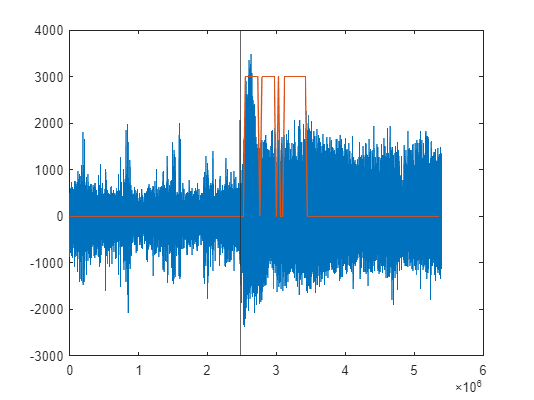

figure() 
[score1, scoretest, amplitude1, time_count1, line_length1] = scoring(bins,dataA, 3500, 300, 300000);
plot(dataA(3,:))
hold on
xline(2480000)
plot(bins,scoretest*3000)
hold off

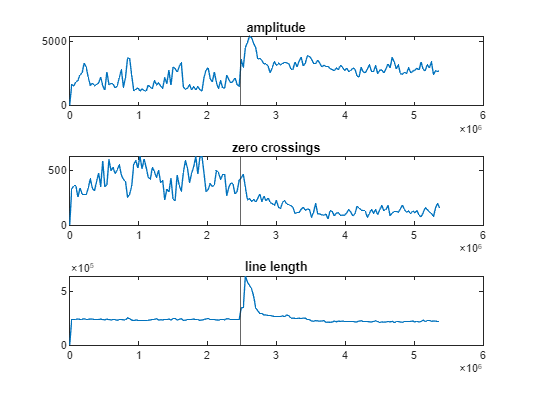

subplot(3,1,1)
plot(bins,amplitude1(:,3))
xline(2480000)
title('amplitude')
subplot(3,1,2)

plot(bins,time_count1(:,3))
xline(2480000)
title('zero crossings')
subplot(3,1,3)
plot(bins,line_length1(:,3))
xline(2480000)
title('line length')

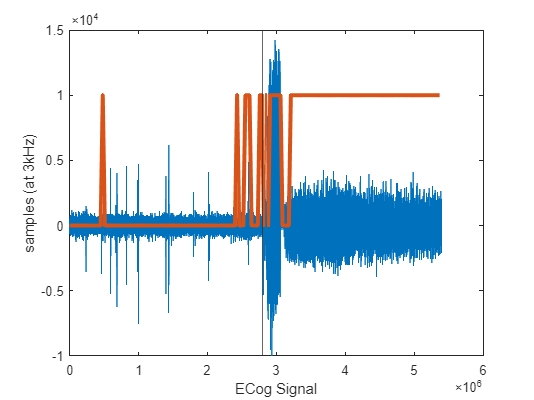


%test how well it works:

[score2, scoretest2, amplitude2, time_count2, line_length2] = scoring(bins,dataB, 3500, 300, 300000);
load("Patient_B-1.mat")
plot(dataB(2,:))
hold on
xline(2800000)
plot(bins,scoretest2*10000, 'LineWidth', 3)
hold off
xlabel('ECog Signal')
ylabel('samples (at 3kHz)')

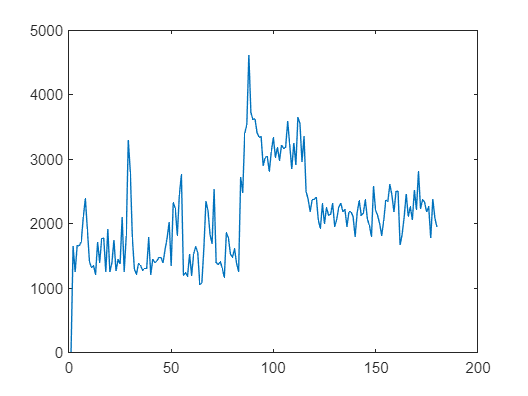

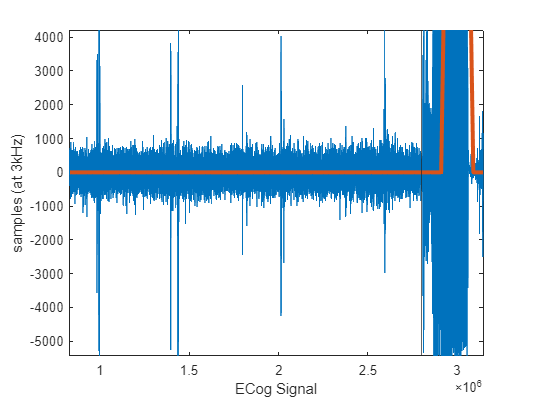

traindata = [amplitude1 line_length1];
testdata = [amplitude2 line_length2];
testClass = classify(testdata, traindata, scoretest, 'linear');
plot(dataB(2,:))
hold on
xline(2800000)
plot(bins,testClass*10000, 'LineWidth', 3)
hold off
xlabel('ECog Signal')
ylabel('samples (at 3kHz)')

# Part 2

d = designfilt("highpassiir", "filterorder", 8, "PassbandFrequency", 100, "SampleRate", 3000);

y = filtfilt(d, dataA')

y =    -0.0010   -0.0010   -0.0006
   35.4928    1.1647   73.7917
   36.9646   -4.3126   94.6321
   31.4525   -3.2493   91.3305
   33.7008   -4.9631   61.0861
   11.1257  -17.0611   39.3636
  -23.7223  -19.1063   25.6093
  -29.3977  -10.7473    5.5839
  -11.7963   -3.4714  -14.4098
  -11.5760   -7.8570  -42.9480


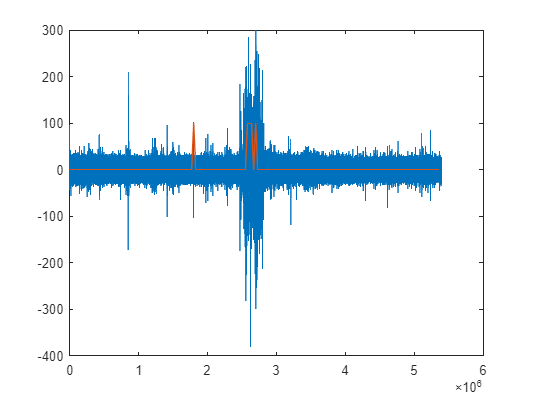

plot(y(:,3))
[scoreHFO, scoretestHFO, amplitudeHFO, time_countHFO, line_lengthHFO] = scoring(bins,y', 400, 7900, 200000);
hold on 
plot(bins,scoretestHFO*100)
hold off

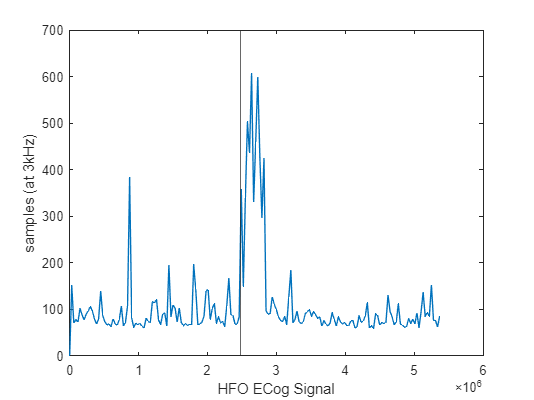

plot(bins,amplitudeHFO(:,3))
xline(2480000)
xlabel('HFO ECog Signal')
ylabel('samples (at 3kHz)')

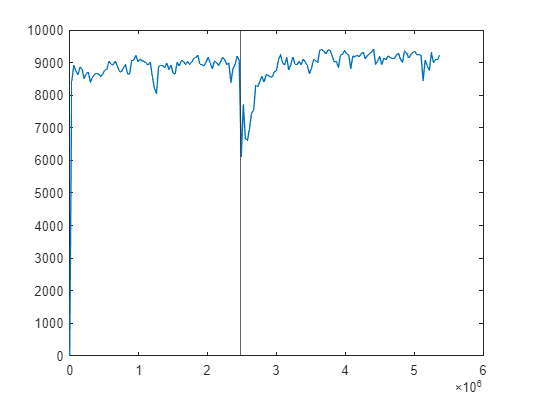




plot(bins,time_countHFO(:,3))
xline(2480000)

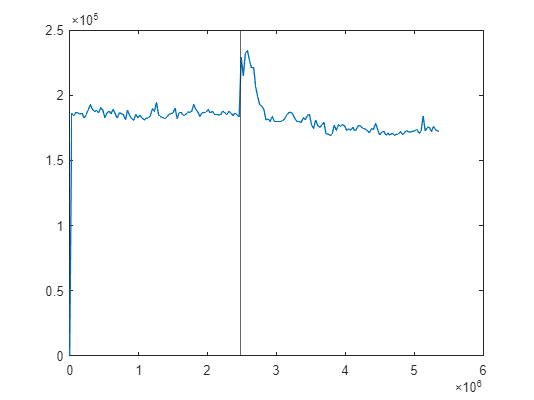

plot(bins,line_lengthHFO(:,3))
xline(2480000)

yt = filtfilt(d, dataB')

yt = 	1.0e+03 *

   -0.0000   -0.0000    0.0000
    0.0188   -0.0657    0.0060
    0.0187   -0.0738    0.0033
    0.0164   -0.0550    0.0087
    0.0059   -0.0516    0.0152
   -0.0015   -0.0400    0.0167
    0.0087   -0.0233    0.0136
   -0.0020   -0.0392    0.0101
   -0.0117   -0.0406    0.0108
   -0.0083   -0.0226    0.0071


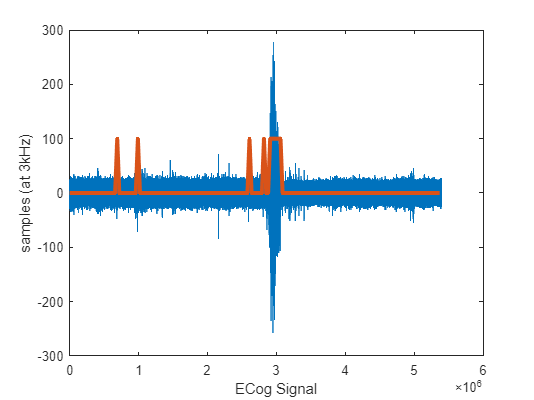

figure()
plot(yt(:,3))
[scoreHFOt, scoretestHFOt, amplitudeHFOt, time_countHFOt, line_lengthHFOt] = scoring(bins,yt', 400, 7900, 200000);
xlabel('ECog Signal')
ylabel('samples (at 3kHz)')
hold on 
plot(bins,scoretestHFOt*100, "LineWidth", 3)
hold off